clear %Limpia las variables
figure(1) %Crea la figura 1

%variables
x=[]; %Variable donde se guarda el vector de la posicion
v=[]; %Variable donde se guarda el vector de la velocidad
F=[]; %Variable donde se guarda el vector de la fuerza

%parametros
m=1; %Masa del cuerpo 1
M=1e20; %Masa del cuerpo 2
G=6.67e-11; %Constante gravitacional
h=0.01; %Diferencial del tiempo, al cambiarlo la simulacion se ve mas rapida o mas lenta

%condiciones iniciales
x=[-1e3;0]; %En t=0, la posicion es x=-1e3 y y=0
v=[0;-2e3]; %En t=0, la posicion es vx=0 y vy=-2e3

%variable externa
F=-G*(m*M/norm(x)^2)*(x/norm(x)); %Vector normal de la fuerza en direccion al cuerpo 2 pero en sentido contrario

F =        26680
           0


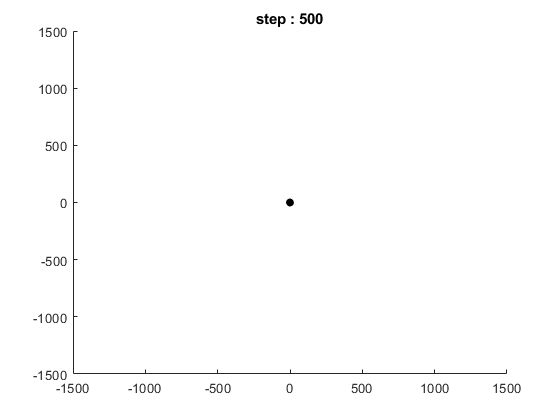


for step=1:500 %De 1 a 500
hold off; 
scatter(x(1),x(2), 'black','filled'); %Se hace plot a la posicion en x y en y
hold on
scatter(0,0,'black','filled'); %Sobre la misma figura se posiciona el cuerpo 2 (sol)
title(['step : ' num2str(step)]); %se cambia el titulo de la grafica
axis([-1.5e3 1.5e3 -1.5e3 1.5e3]); %se sostienen los limites de los ejes
pause(0.01); %Para la ejecucion 0.01 segundos

%guardar valor anterior
xa=x; %Guardamos el vector de la posicion actual
va=v; %Guardamos el vector de la velocidad actual

%paso integraci√≥n
F=-G*(m*M/norm(xa)^2)*(xa/norm(xa)); %Se obtiene el vector de la fuerza
vpm = va + (h/2)*(F/m); %Actualiza el valor de la velocidad integrando la aceleracion
xpm = xa + (h/2)*va; %Actualiza el valor de la posicion integrando la velocidad
F=-G*(m*M/norm(xpm)^2)*(xpm/norm(xpm)); %Calcula la fuerza con los nuevos valores de posicion y velocidad
v = va + h*(F/m); %Cambia la velocidad con la integral de la nueva fuerza
x = xa + h*vpm; %Cambia la posicion con la integral de la nueva fuerza
end

%2: Si se cambian las condiciones iniciales
%Al cambiar la posicion inicial de la particula cambia el centro de giro de
%la particula
%Si se cambia la velocidad, rota en torno al cuerpo inicial m de forma mas
%rapida o mas lenta


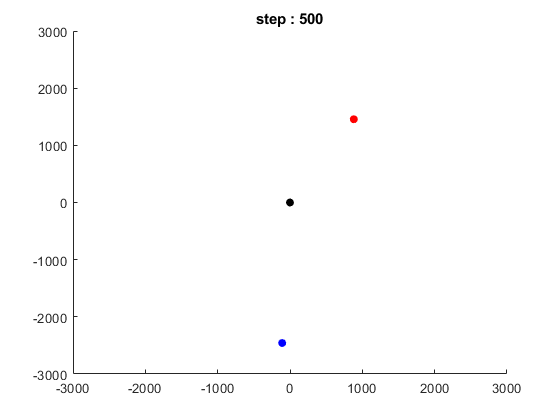

%%Movimiento de otra particula
clear
figure(2)
%variables
x=[];
v=[];
F=[];
%parametros
m=1;
m2 = 5;
M=1e20;
G=6.67e-11;
h=0.1;
%condiciones iniciales
x=[-2e3;0];
x2=[1.2e3;0];
v=[0;-2e3];
v2 = [0;2.5e3];
%variable externa
F=-G*(m*M/norm(x)^2)*(x/norm(x));
F2=-G*(m2*M/norm(x2)^2)*(x2/norm(x2));

for step=1:500
hold off;
%plot(x(1),x(2),'.','Color','black')
scatter(x(1),x(2), 'blue','filled');
hold on
%plot(x2(1),x2(2),'.','Color','red')
scatter(x2(1),x2(2), 'red','filled');
hold on
scatter(0,0,'black','filled');
title(['step : ' num2str(step)]);
axis([-3e3 3e3 -3e3 3e3]);
pause(0.001);

%guardar valor anterior
xa=x;
va=v;
xa2 = x2;
va2 = v2;

%paso integracion
F=-G*(m*M/norm(xa)^2)*(xa/norm(xa));
vpm = va + (h/2)*(F/m);
xpm = xa + (h/2)*va;
F=-G*(m*M/norm(xpm)^2)*(xpm/norm(xpm));
v = va + h*(F/m);
x = xa + h*vpm;

%Particula 2
F2=-G*(m2*M/norm(xa2)^2)*(xa2/norm(xa2));
vpm2 = va2 + (h/2)*(F2/m2);
xpm2 = xa2 + (h/2)*va2;
F2=-G*(m2*M/norm(xpm2)^2)*(xpm2/norm(xpm2));
v2 = va2 + h*(F2/m2);
x2 = xa2 + h*vpm2;
end